Polinomios

Declarar un polinomio es con vectores

p = [2 0 -6 5];

Para evaluar el polinomio en un punto es

value01 = polyval(p,2);

Graficar el siguiente polinomio

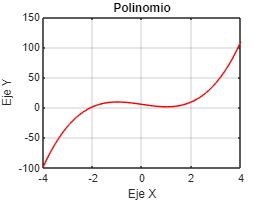

p = [2 0 -6 5];
xx = linspace(-4,4,50);
yy = polyval(p,xx);
plot(xx,yy,'r')
title('Polinomio')
xlabel('Eje X')
ylabel('Eje Y')
grid on

Graficar un polinomio mónico con las siguiente raíces

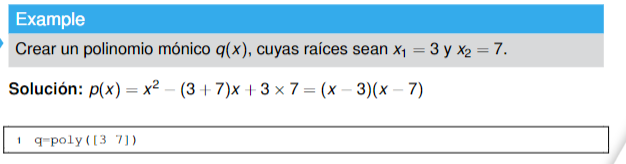

q = poly([3 7])

q =      1   -10    21


Ejercicio

Solution

pm = poly([3 3 3 3 4 4 6])

pm =            1         -26         286       -1728        6201      -13230       15552       -7776


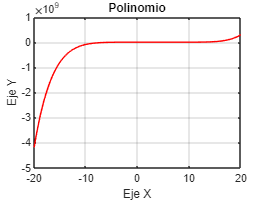

xx = linspace(-20, 20, 100);
yy = polyval(pm,xx);
plot(xx,yy,'r');
title('Polinomio')
xlabel('Eje X')
ylabel('Eje Y')
grid on

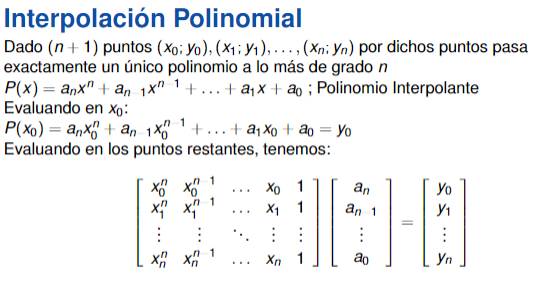

x=[0 3 4 7]'

x =      0
     3
     4
     7


y=[5 2 6 9]'

y =      5
     2
     6
     9


M=[x.^3 x.^2 x ones(4,1)] % Matriz de Vandermonde con última columna de cuatro unos

M =      0     0     0     1
    27     9     3     1
    64    16     4     1
   343    49     7     1


M=vander(x)

M =      0     0     0     1
    27     9     3     1
    64    16     4     1
   343    49     7     1


p=M\y %inv(M)*y

p =    -0.2857
    3.2500
   -8.1786
    5.0000


Otra forma

p = polyfit(x,y,length(x)-1)

p =    -0.2857    3.2500   -8.1786    5.0000


La función polyfit

polyfit(x,y,m), donde:

x, y son vectores de longitud n+1

x = vector de abscisas

y = vector de ordenadas

m = grado del polinomio

Si m = n, entonces polyfit construye un polinomio interpolado de grado <= n

Si m < n, entonces polyfit construye un polinomio de ajuste para mínimos cuadrados

La f(x) es igual a sen(x)*e^x

x=[2 2.75 4]';
f=@(x) (sin(x).*exp(x))

f = function_handle with value:
    @(x)(sin(x).*exp(x))


y=f(x);
p2=polyfit(x,y,2)

p2 =   -18.4170   86.4824  -92.5780


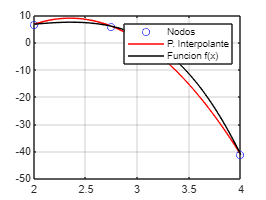

xx=linspace(2,4);
yy1=polyval(p2,xx);
yy2=f(xx);
plot(x,y,'ob',xx,yy1,'r',xx,yy2,'k')
grid on
 legend('Nodos','P. Interpolante','Funcion f(x)')

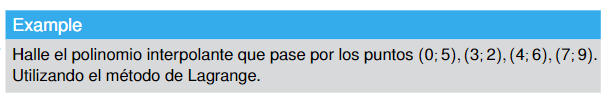

Solucion

x=[0 3 4 7]'

x =      0
     3
     4
     7


y=[5 2 6 9]'

y =      5
     2
     6
     9


p=lagrange(x,y)

p =    -0.2857    3.2500   -8.1786    5.0000


x=[0 3 4 7]';
y=[5 2 6 9]';
M=tabladif(x,y)

M =          0    5.0000   -1.0000    1.2500   -0.2857
    3.0000    2.0000    4.0000   -0.7500         0
    4.0000    6.0000    1.0000         0         0
    7.0000    9.0000         0         0         0


p=polynewton(x,y)

M =          0    5.0000   -1.0000    1.2500   -0.2857
    3.0000    2.0000    4.0000   -0.7500         0
    4.0000    6.0000    1.0000         0         0
    7.0000    9.0000         0         0         0


p =    -0.2857    3.2500   -8.1786    5.0000
